# Noise-vocoded speech demo 

G.FG 2022

% Files and dirs
clear all
dirinput = 'C:\Users\gfraga\scripts_neulin\Misc\Noise_demos';
cd(dirinput)
% drop down options
opts_exc = ["noise","sine","F0_value","-F0_value"]; % white noise, sinusoid, sine-, or alternating-phase harm. complexes
opts_mapping = ["n","i"] ;% normal or inverted 
opts_filters = ["greenwood","linear","mel","log"];%
opts_EnvelopeExtractor = ["hilbert","half","full","hilbertNoTheta"] ;% Select method to extract amplitude (Hilbert recommended)


% Controls --------------------------

## Input settings

exc = opts_exc(1);
mapping = opts_mapping(1);
filters = opts_filters(1);
EnvelopeExtractor = opts_EnvelopeExtractor(2);
smooth= 10;
nCh = 16;
MinFreq= 50;
MaxFreq = 5000;
Srate = 22050;
%   [x,path] = uigetfile('*.wav');
%         if isequal(x,0)
%            disp('No file selected');
%         else 
%            disp(['input file = ', fullfile(path,x)]);
%         end
x = audioread('MAX00043.wav');
OutFile = ' output.wav';
% -------------------------------------------------

## Run vocoding function

  
[x_nv]=vocode(exc, mapping, filters, EnvelopeExtractor, smooth, nCh, x, Srate, MinFreq, MaxFreq);

### Plots

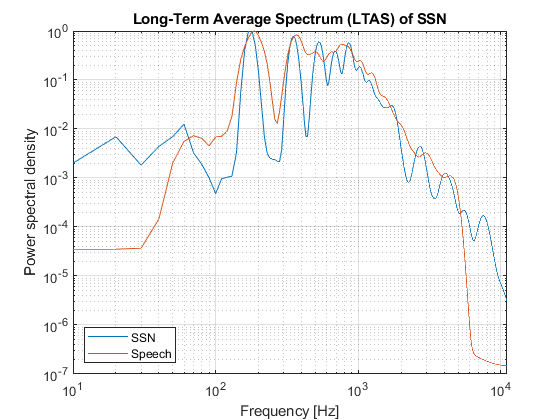

 noct = 6; 
% LTAS:
figure; 
iosr.dsp.ltas(x,Srate,'noct',noct,'graph',true,'units','none','scaling','max0','win',Srate/10);  % requires the IoSR Matlab Toolbox
hold on; 
iosr.dsp.ltas(x_nv,Srate,'noct',noct,'graph',true,'units','none','scaling','max0','win',Srate/10);
%xline(50, '--k'); xline(5000, '--k'); hold off;
title('Long-Term Average Spectrum (LTAS) of SSN');
legend({'SSN', 'Speech'}, 'Location', 'SW');

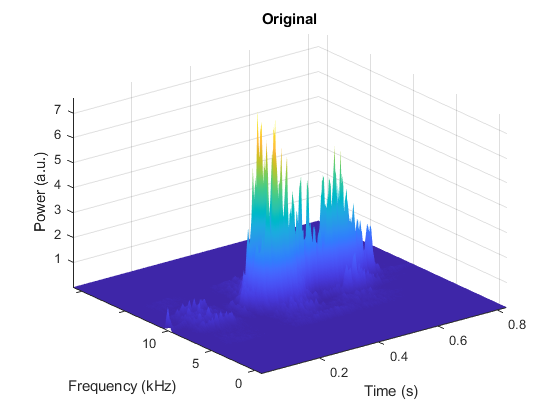


% Spectrogram
parameter = [];
parameter.fsAudio = Srate;
parameter.zeroPad = Srate/10;
[spec_nv,f,t] = stft(x_nv',Srate);                              % requires the MATLAB_TSM-Toolbox_2.02

figure;
surf(t,f,abs(spec_nv)); hold on; set(gcf,'renderer','zbuffer');
shading interp; axis tight;
yticklabels(0:5:10);
title('Original');
xlabel('Time (s)');
ylabel('Frequency (kHz)');
zlabel('Power (a.u.)');


figure;
surf(t,f,abs(spec_nv)); hold on; set(gcf,'renderer','zbuffer');
set(gca,'zscale','log');  set(gca,'yscale','log');
shading interp; axis tight;
title('Log scale');

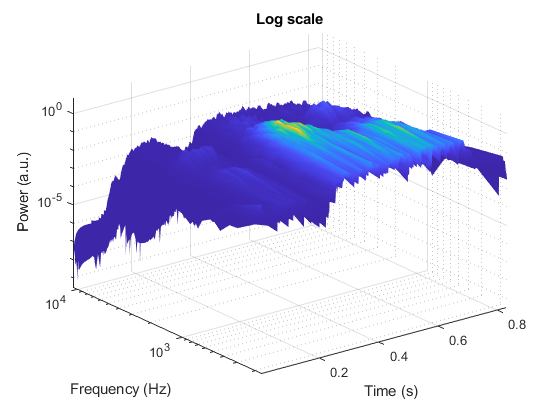

xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Power (a.u.)');


% 
% 
% xline(50, '--k'); xline(5000, '--k'); hold off;
% title('Long-Term Average Spectrum (LTAS) of SSN');
% legend({'SSN', 'Speech'}, 'Location', 'SW');
% 
% % Spectrogram
% parameter = [];
% parameter.fsAudio = fsS;
% parameter.zeroPad = fsS/10;
% [spec_SSN,f,t] = stft(SSN{1}',parameter);                              % requires the MATLAB_TSM-Toolbox_2.02
% 
% figure;
% surf(t,f,abs(spec_SSN)); hold on; set(gcf,'renderer','zbuffer');
% shading interp; axis tight;
% yticklabels(0:5:10);
% title('Original');
% xlabel('Time (s)');
% ylabel('Frequency (kHz)');
% zlabel('Power (a.u.)');
% 
% figure;
% surf(t,f,abs(spec_SSN)); hold on; set(gcf,'renderer','zbuffer');
% set(gca,'zscale','log');  set(gca,'yscale','log');
% shading interp; axis tight;
% title('Log scale');
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% zlabel('Power (a.u.)');


%function [wave,varargout]=vocode(exc, mapping, filters, EnvelopeExtractor, smooth, nCh, x, Srate, MinFreq, MaxFreq, varargin)
 % function vocode_64bits(exc, mapping, filters, EnvelopeExtractor, smooth, nCh, InFile, OutFile)
%
%  exc - 'noise', 'sine', 'F0_value', or '-F0_value' for: white noise, sinusoid, sine-, or alternating-phase harm. complexes
%   as excitation for the temporal envelopes of the filtered waveforms
%  mapping - 'n'(ormal) or 'i'(nverted)
%  filters - 'greenwood', 'linear', 'mel' or 'log'
%  EnvelopeExtractor - How is the amplitude envelope extracted? 'half' or
%  'full', or 'hilbert' or 'hilbertNoTheta'
%  smooth - filter cutoff frequency
%  nCh - the number of channels
%  x - input filename in quotes, e.g., 'heed.wav'
%  wave - output filename in quotes, e.g., 'heed2.wav'
%
% For example, to get an interesting variety of outputs with 6 channels,
% do the following commands:
% vocode('noise','n','greenwood','half',320,6,'sent.wav','nn320.wav')
% vocode('noise','i','greenwood','half',320,6,'sent.wav','ni320.wav')
% vocode( 'sine','n','greenwood','half',320,6,'sent.wav','sn320.wav')
% vocode( 'sine','i','greenwood','half',320,6,'sent.wav','si320.wav')
% vocode('noise','n','greenwood','half', 30,6,'sent.wav', 'nn30.wav')
% vocode('noise','i','greenwood','half', 30,6,'sent.wav', 'ni30.wav')
% vocode( 'sine','n','greenwood','half', 30,6,'sent.wav', 'sn30.wav')
% vocode( 'sine','i','greenwood','half', 30,6,'sent.wav', 'si30.wav')
% These commands are contained in file 'run.m'
%
% For harmonic complexes, e.g. sine and alternating phase with F0= 100 Hz, type:
% vocode(  '100','n','greenwood','half', 30,6,'sent.wav', 'csn30.wav')
% vocode( '-100','n','greenwood','half', 30,6,'sent.wav', 'can30.wav')
% To specify the F0 and phase for each band separately you can do this:
% vocode( '-100 72 55 200 144 72','n','greenwood','half', 30,6,'sent.wav',
% 'mixed30.wav')
% You can produce one or more "empty" channels by specifying an F0 of 0:
%  vocode( '-100 72 0 200 144 72','n','greenwood','half', 30,6,'sent.wav',
% '1empty.wav')
% The output file is in .WAV format and can be played using whatever
% package you like, or just type: play filename
%

